b = 1.02;
c = 0.08;
h = 0.8603;
lambda = pi/10;
V = 5; % let's only reduce the speed
a = 0.347;
g = 9.81;
m = 84;

k1 = b^2/((V^2*sin(lambda) - b*g*cos(lambda))*m*a*c*sin(lambda));
k2 = b*g/(V^2*sin(lambda) - b*g*cos(lambda));

% k1 = 5;
% k2 = 1;

sys_tf_uns = get_bicycle_fb_tf(h, V, a,b,k1,k2,c,lambda);
sys_tf_uns

sys_tf_uns =
 
    -0.4925 s - 7.007
  ---------------------
  s^2 - 3.413 s - 59.97
 
Continuous-time transfer function.



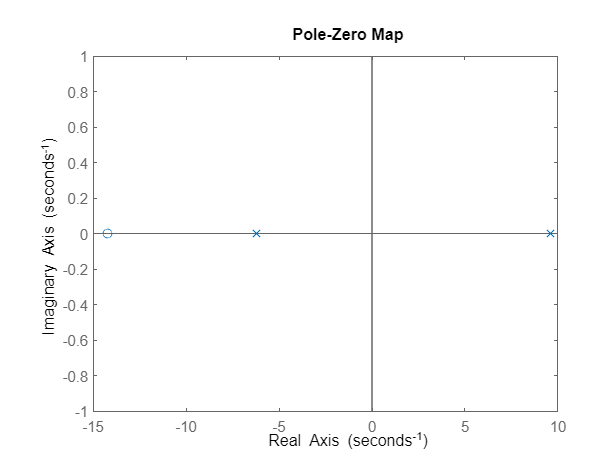

pzmap(sys_tf_uns)

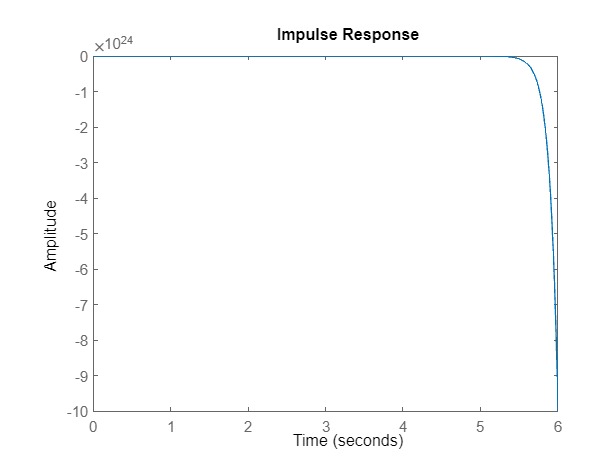

impulse(sys_tf_uns)

**state space**

% ccf
A = [
    0                                                       1;
    g/h - k2*(V^2*h-a*c*g)*sin(lambda)/(b*h^2)    -a*V*sin(lambda)/(b*h)*k2
];
B = [
    0;
    1
];

C = [(V^2*h-a*c*g)*sin(lambda)/(b*h^2)*k1 a*V*sin(lambda)/(b*h)*k1];
D = 0;


sys_ss = ss(A,B,C,D)

sys_ss =
 
  A = 
          x1     x2
   x1      0      1
   x2  59.97  3.413
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
            x1       x2
   y1   -7.007  -0.4925
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



eig(A)

ans =    -6.2229
    9.6363


pole(sys_tf_uns)

ans =     9.6363
   -6.2229


**Stability Analysis**

Q = eye(length(A));
P = lyap(A,Q);

if all(eig(P) > 0)
    disp('The system is stable.')
else
    disp('The system is not stable.')
end

The system is not stable.


## **Designing Controller and Observer**

pole(sys_tf_uns)

ans =     9.6363
   -6.2229


**Pole placement**

new_poles = [-6.6567+12.6826i  -6.6567-12.6826i]

new_poles =   -6.6567 +12.6826i  -6.6567 -12.6826i


K = place(A,B,new_poles)

K =   265.1257   16.7269


A_pp = A-B*K;
B_pp = B;
C_pp = C;
D_pp = D;

sys_ss_pp = ss(A_pp, B_pp, C_pp, D_pp);
sys_ss_pp

sys_ss_pp =
 
  A = 
           x1      x2
   x1       0       1
   x2  -205.2  -13.31
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
            x1       x2
   y1   -7.007  -0.4925
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



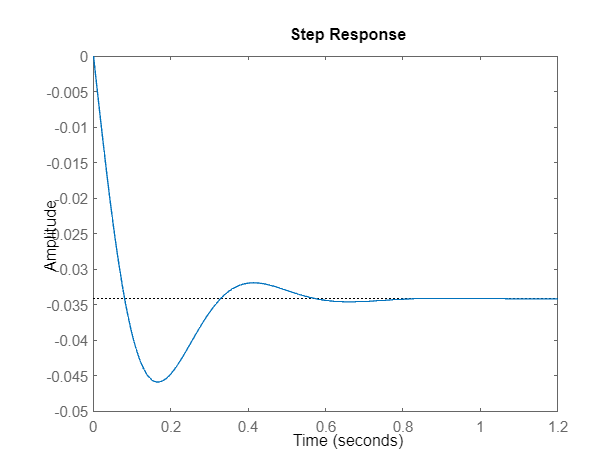

step(sys_ss_pp)

**stability analysis of the system + state FB:**

Q = eye(length(A_pp));
P = lyap(A_pp,Q);

if all(eig(P) > 0)
    disp('The system is stable.')
else
    disp('The system is not stable.')
end

The system is stable.


**Luenberger Observer**

% observer_poels = [2*real(new_poles(1)), 2*real(new_poles(2))];
observer_poles = [-12, -12]

observer_poles =    -12   -12


L_t = acker(A', C', observer_poles);
L = L_t'

L =    -1.9776
  -27.5224


A_obs = A-L*C

A_obs =   -13.8574    0.0260
 -132.8930  -10.1426


B_obs = [B L] % input is [u Y]'

B_obs =          0   -1.9776
    1.0000  -27.5224


C_obs = eye(length(A_obs)) % since we want all the states

C_obs =      1     0
     0     1


D_obs = zeros(size(B_obs))

D_obs =      0     0
     0     0
